# Spline interpolation

## Setup

% the given 2 parameter function to interpolate
f = @(t) @(x) sin(5*pi*x)*cos(10*pi*t) + 2*sin(7*pi*x)*cos(10*pi*t);

% 'time' variable discretization fixed by the task description.
time_step = .02;
T = 0:time_step:1;

% linear grid evaluation for displaying the interpolated function.
discrete_unit = .001;
X = 0:discrete_unit:1;

% domain boundaries
from = 0;
until = 1;

number_of_knots = 50;


## Liner interpolation

### Calculate interpolated points (inefficent but works)


% preallocated result vector
YT = zeros(1/time_step+1, 1/discrete_unit+1);

for t = 0:time_step:1
    ti = round(t/time_step) + 1;
    for x = 0:discrete_unit:1
       y = linear_spline_interpolation(f(t), from, until, number_of_knots, x);
       xi = round(x/discrete_unit)+1;
       YT(ti,xi) = y;
    end
end


### Display results

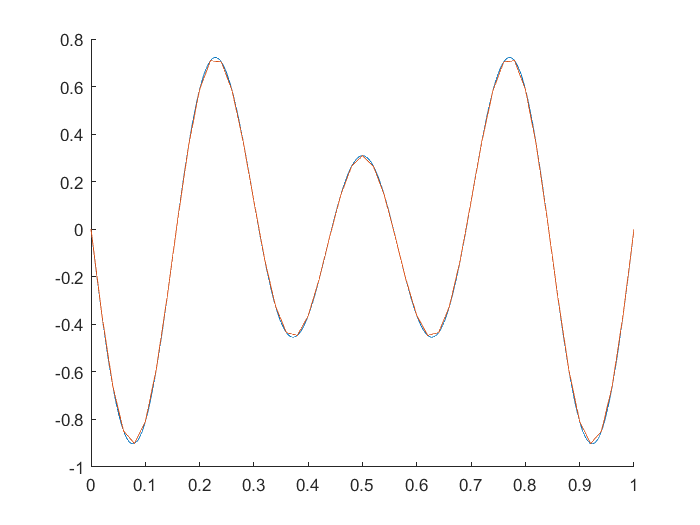

hold on;
f0 = f(33/50);
plot(X, f0(X));
plot(X,YT(34,:));
hold off;

## Natural cubic splines

% preallocate memory
expectedResult = zeros(1/time_step+1,1/discrete_unit+1);
actualValues = zeros(1/time_step+1,1/discrete_unit+1);

for t = 0:time_step:1
    xi = round(x/discrete_unit)+1;
    ti = round(t/time_step) + 1;
    interpolationPoints = from:(1/number_of_knots):until;
    ft = f(t);
    % calculated expection with matlab built in functions' 
    expectedResult(ti, :) = csapi(interpolationPoints, ft(interpolationPoints), X);
    % calculate interpolation function
    interpolated = natural_cubic_spline(ft,from, until, number_of_knots);
    for x = 0:discrete_unit:1
        xi = round(x/discrete_unit) + 1;
        actualValues(ti,xi) = interpolated(x);
    end
end


### Display results

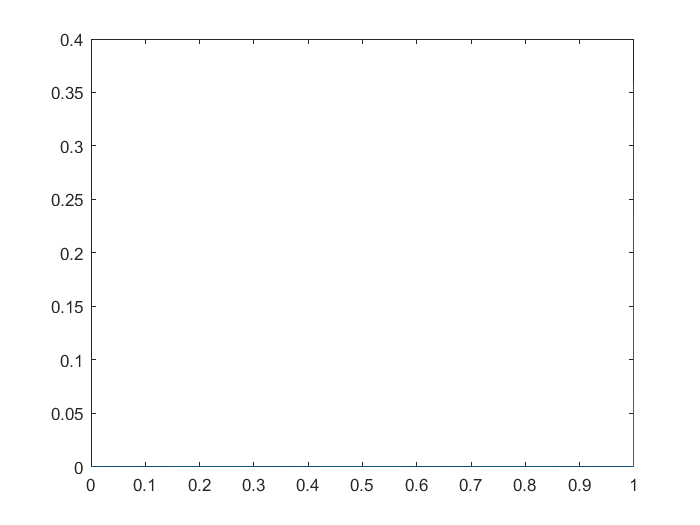

hold on;
f0 = f(33/50);
plot(X, f0(X));

plot(X, actualValues(34,:));











